## Lab 5, Part 3: Moutain Car Problem

### 2.1 Introduction

- The objective of this part of the laboratory is to learn how to define the environment for a custom-problem in deep reinforcement learning.

- You will need the Reinforcement Learning Toolbox and the Deep Learning Toolbox installed.

- **Important: You need to read the instructions in the pdf file ACS61011_Lab5_Mountain_Car.pdf on Blackboard.**

### 2.2 Task description

In all the tasks up to this point we have used predefined environments for the reinforcement learning system. In practice, when encountering new problems, you will need to setup and code your own custom environment for the reinforcement agent to explore and experience. This means that you need to know how to setup custom environments (or you will only ever be able to study problems that someone else has setup for you – highly limiting!). 

In this task you will design and implement an environment for a classic reinforcement learning problem – the mountain car, which does not have a predefined Matlab environment – you will build it, and then train a reinforcement learning agent to solve it. 

The mountain car problem (Fig. 1) is a classic one in reinforcement learning, partly because it is difficult for conventional controllers to solve. The idea is that a car is stuck in a valley and needs to escape but its engine is not powerful enough to climb the mountain directly, so it must roll back and forth to build momentum in order to reach the goal state (where the goal state is position 𝑥>0.5).

The dynamics of the car are described by

                        
$$\ddot{x}_t = 0.001u_t-0.0025 \cos 3 x_t$$


where $\ddot{x}_t$ is the acceleration of the car.

In the reinforcement learning problem we define reward as in Sutton and Barto, which is just to specify a discrete reward of -1 for every step the mountain car takes to reach the goal, or until the episode terminates – i.e. a small negative reward to encourage the agent to reach the goal state in as few steps as possible.

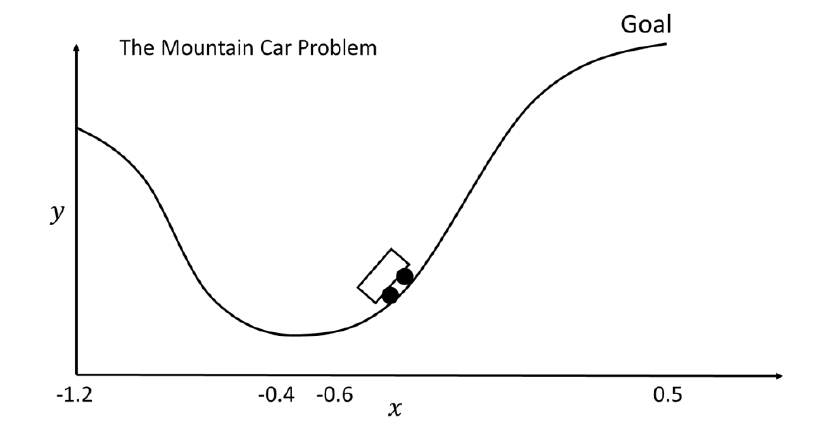

Figure 1. Illustration of the mountain car problem.      

**YOU NEED TO WRITE THE CUSTOM FUNCTIONS FOR THE STEP DYNAMICS AND INITIALISATION**

**Check the pdf file on Blackboard for more detailed instructions.**

**Then when you have written the step dynamics and initialisation functions you can run the code below.**

### 2.3 Environment and Critic definition

We use your custom functions for the step dynamics and the initial position here so make sure they are written and saved to this same working directory with the names

- stepDynamics.m

- initialDynamics.m

The code below sets up the reinforcement learning problem for mountain car using these custom functions that you have written.

% Reinforcement learning for mountain car
 
clear all
 
% define the random number seed for repeatable results
rng(1,'twister');
 
% environment definition for mountain car
 
% observation info
ObservationInfo = rlNumericSpec([2 1]);
ObservationInfo.Name = 'States';
ObservationInfo.Description = 'Position and Velocity';
 
% action info
ActionInfo = rlFiniteSetSpec([-1 0 1]);
ActionInfo.Name = 'Action';
 
% environment - YOUR Functions are used here
env = rlFunctionEnv(ObservationInfo,ActionInfo,'stepDynamics','initialDynamics');
 
% get observation and specification info
stateInfo = getObservationInfo(env);      % get state info
stateDimension = stateInfo.Dimension;     % get continuous state dimension
actionInfo = getActionInfo(env);          % get action info 
numActions = length(actionInfo.Elements); % number of discrete actions
 
% Define a Q-function network with state-only input (known in Matlab as a critic)
 
% Create a shallow neural network to approximate the Q-value function
net = [imageInputLayer(stateDimension,'Normalization','none','Name','States')
    fullyConnectedLayer(24)
    reluLayer
    fullyConnectedLayer(numActions)];
 
% Create the critic using the network
critic = rlQValueRepresentation(net,stateInfo,actionInfo,'Observation',{'States'});

 

### 2.4 Define a Deep Q-learning agent to solve the mountain car problem

%% Define agent and train
% agent options
agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...
    'TargetUpdateMethod',"periodic", ...
    'TargetUpdateFrequency',4, ...
    'ExperienceBufferLength',100000, ...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',256);
 
% define the agent
agent = rlDQNAgent(critic,agentOpts);
 
% specify reinforcement learning training options
trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 100, ...
    'MaxStepsPerEpisode', 1000, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward');
 
% train the agent
trainingStats = train(agent,env,trainOpts);


### 2.5 Simulate the trained agent

Simulate the trained agent to examine its performance. 

%% Simulate
simOptions = rlSimulationOptions('MaxSteps',1000); % simulation options
experience = sim(env,agent,simOptions); % log experience
totalReward = sum(experience.Reward); % extract reward

% plot simulation results
figure;

% plot training rewards
subplot(2,1,1);
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeReward);
hold on;
plot(trainingStats.EpisodeIndex,trainingStats.AverageReward);
title('Training Rewards');
xlabel('Episode');
ylabel('Reward');
legend('Episode Reward','Average Reward','Location','SouthEast');
nt = length(experience.Reward.Time);
States = experience.Observation.States.Data;
xvals = [-1.2:0.1:0.6];
yvals = sin(3*xvals);
cumReward = cumsum(experience.Reward.Data);



(Note, to watch the mountain car it might be necessary to copy and paste the code below into the command window to execute it, otherwise the figure sometimes only plots on completion of the simulation.)

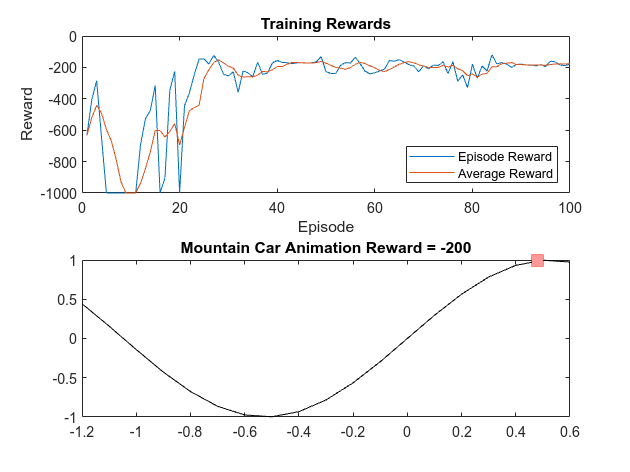

%% Simulate
% Fix the random generator seed for reproducibility
rng(1,'twister');
 
% plot animation
for i = 1:nt
    subplot(2,1,2); % new subplot
    cla; % clear plot
    plot(xvals,yvals,'k'); % plot mountain
    hold on
    x = States(1,1,i); % horizontal position of mountain car
    y = sin(3*x); % height of mountain car
    plot(x,y,'sq','MarkerSize',10,'MarkerEdgeColor','red','MarkerFaceColor',[1 .6 .6]);
    title(['Mountain Car Animation Reward = ' num2str(cumReward(i))])
    pause(0.01)
end

totalReward = sum(experience.Reward)              % extract reward

totalReward = -200

% the end of lab part